**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221 **

clear;
clc;

**Q1. Load the Exercise 8 data set into matlab. This data comprises a set of 100 time domain data records each comprised of approximately 10,000 samples. This data is noisy, contains measurement discontinuities and spurious data samples. Additionally, each time domain record contains the event denote by the variable event somewhere within each data record.**

load('Exercise_8_data');

**Q3 Determine whether the data comprises constant sampling intervals or stochastic sampling intervals. Discuss the data analysis differences and distinctions that arise for these two cases. **

- **In the case of stochastic sampling, develop and apply an appropriate methodology to enable correct data analysis and discuss why not correcting for the stochastic sampling is problematic. Would it be problematic in *****all *****cases?**

% Plotting the time interval difference
display('Sample interval 1 to 25'); 

Sample interval 1 to 25


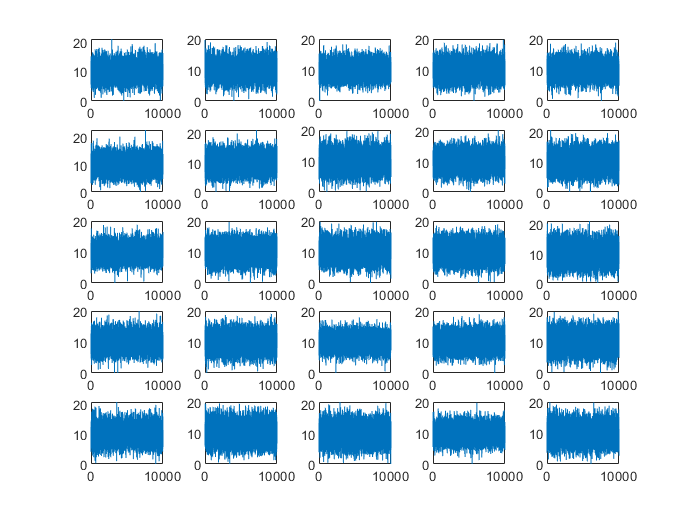

figure();

for i = 1:25

    subplot(5, 5, i);
    plot(diff(data(i).time))
        
end

hold off;

display('Sample interval 26 to 50'); 

Sample interval 26 to 50


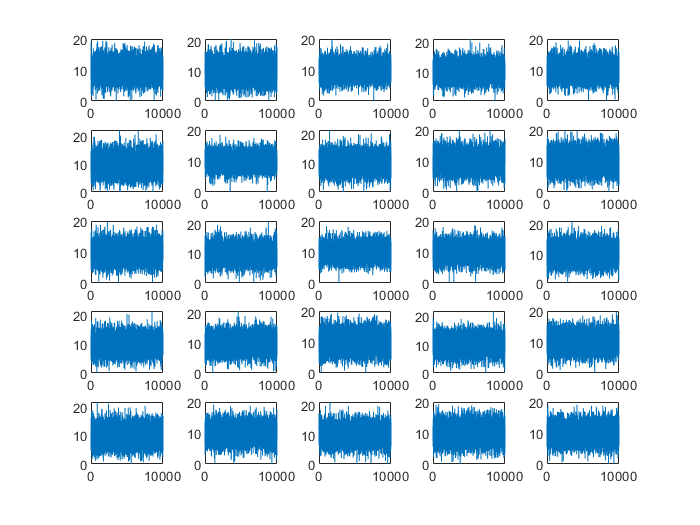

figure();
j = 1;
for i = 26:50
    
    subplot(5, 5, j);
    plot(diff(data(i).time))
    j = j + 1;
    
end
hold off;


display('Sample interval 51 to 75'); 

Sample interval 51 to 75


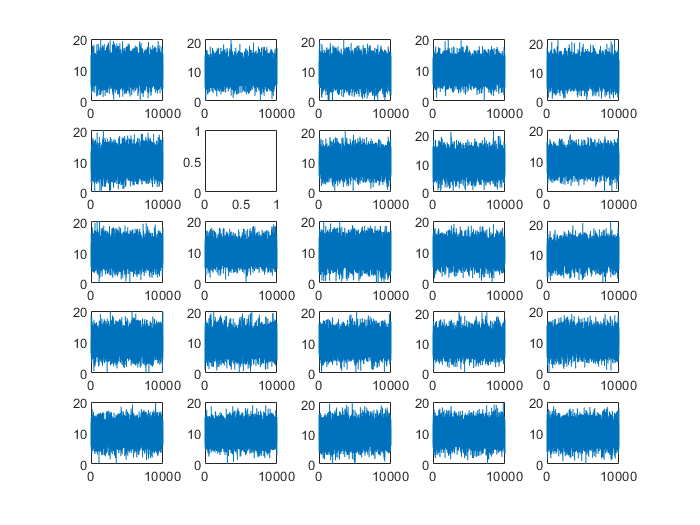

figure();
j = 1;
for i = 51:75
    
    subplot(5, 5, j);
    plot(diff(data(i).time))
    j = j + 1;
    
end

display('Sample interval 76 to 100'); 

Sample interval 76 to 100


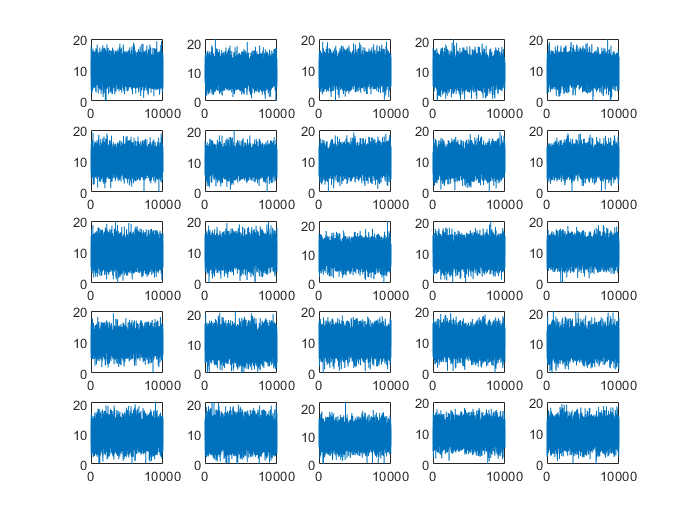

figure();
j = 1;
for i = 76:100
    
    subplot(5, 5, j);
    plot(diff(data(i).time))
    j = j + 1;
    
end

Finding the indices of duplicate measurements

% Sanitizing the data to identify duplicate timestamps
duplicate_time_list = [];
data2 = data;

for i = 1:100

    duplicate_index = find(diff(data(i).time) == 0);
    
    if isempty(duplicate_index) == 0
        data2(i).time(duplicate_index) = [];
        data2(i).x(duplicate_index) = [];
    end
    
    duplicate_time_list = [duplicate_time_list; duplicate_index];
    
end

check = data2(57).time

check =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


data2(57) = [];

% Number of points we need to sample
samples = 2^13;

sanitized_data = data2;
for i = 1:99
 
    uniform_series = linspace(min(data2(i).time), max(data2(i).time), samples);
    x = data2(i).time;
    y = data2(i).x;
    y_corrected_data = spline(x, y, uniform_series);
    sanitized_data(i).x = y_corrected_data;
    sanitized_data(i).time = uniform_series;
    
end

% Plot difference in time window width after correction
sampling_interval_difference = round(diff(uniform_series), 2)

sampling_interval_difference =    12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100   12.2100


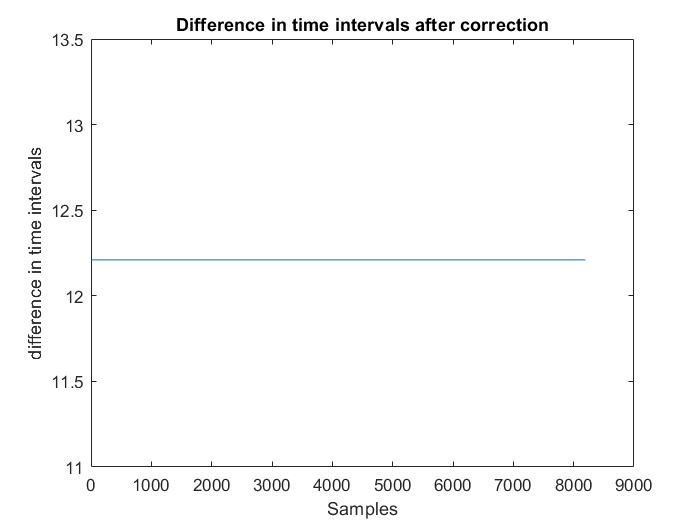

figure();
plot(sampling_interval_difference)
title('Difference in time intervals after correction');
xlabel('Samples');
ylabel('difference in time intervals');

**Ans:**

A lot of variation captured in the above 4 sets of 25 subplots indicate that the data comprises of  stochastic sampling intervals. The subplots capture the differences in the time intervals. Since, the variation isn't constant or a graphically a straight line, this indicates the presence of stochastic sampling intervals. 

Stochastic sampling is common in the real datasets as the stochastic datasets come from event driven systems. For example, data about when the customers purchased articles would be stochastic sampling interval. Stochastic samplings are harder to deal with as almost all of the techniques for dealing with time series data, for example, Neural Networks, digital filters, Fourier Transforms would assume that the data is constant sample interval. Therefore, the stochastic sampling can be problematic in case of time series data analysis.

Stochastic sampling is not a problem in cases where we need to deal with only the data samples. For example, if we want to draw a histogram of the collected data to understand the data distribution, the stochastic data sampling would not be a problem as the histogram of the data samples does not depend on the time intervals.

We have used a methodology to correct for the stochastic sampling. We have used cubic spline interpolation method to estimate data points at constant time intervals. Once we have constant time intervals we can use the data analysis methodologies for time series data analysis. The above plot having straight line indicates that now we have constant time sample intervals.

**Q4 Determine whether any of the data records contain coarsely quantized data and discuss the impacts and concerns that arise for coarsely quantized data sets. **

**How would you correct for coarsely quantized data and is it “correctable”? **

threshold = 2^6

threshold = 64


for i = 1:100

    coarsely_quantized_array = find(length(unique(data(i).x)) < threshold);
    
end

length_coarsely_quantized = length(coarsely_quantized_array)

length_coarsely_quantized = 0

**Ans:**

While digitizing the continuous data signal x(kT), we get certain quantization data values. Real data comprises of continuous data signal x(kT) and some noise n(kT) associated with the data signal. We can never measure some data without the noise and the method of denoising is used to get rid of the noise from the data signal. So, while quantizing the data, we are actually quantizing the data signal and the noise signals. If there are more than 64 quantization levels over the data signal's dynamic range, we can linear model the system into y(kT) = x(kT) + n(kT) + nq(kT) where noise quantization nq(kT) = u(square(delta)/12), where delta is the size of quantization cell.

If there are less than 64 quantization levels, the linear model discussed above does not work and we have non linear, discontinious model y(kT) =  x(kT) + n(kT) + nq(kT(xkT) + n(kT)), where quantization noise is conditioned on x(kT) and this is called coarse quantization, which is difficult to deal with as coarse quantization means loss of information. Nobody knows a solution to solve this kind of non-linear, discontinuous model and thus, coarsely quantized data is not "correctable".

**Q5 Apply median filtering to remove all spurious data samples. Discuss the assumption that median filtering makes. **

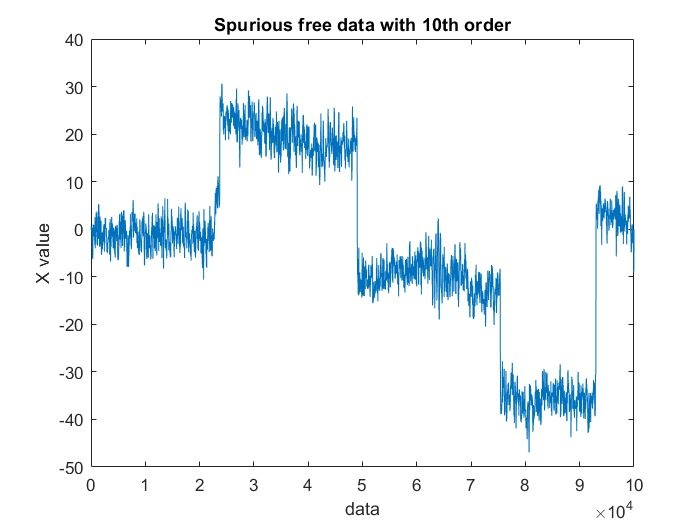

spurious_free_data = sanitized_data;
spurious_free_data2 = sanitized_data;

for i = 1: length(sanitized_data)   
    spurious_free_data(i).x = medfilt1(sanitized_data(i).x, 10);
end

plot(spurious_free_data(1).time, spurious_free_data(1).x)
title('Spurious free data with 10th order');
xlabel('data');
ylabel('X value');

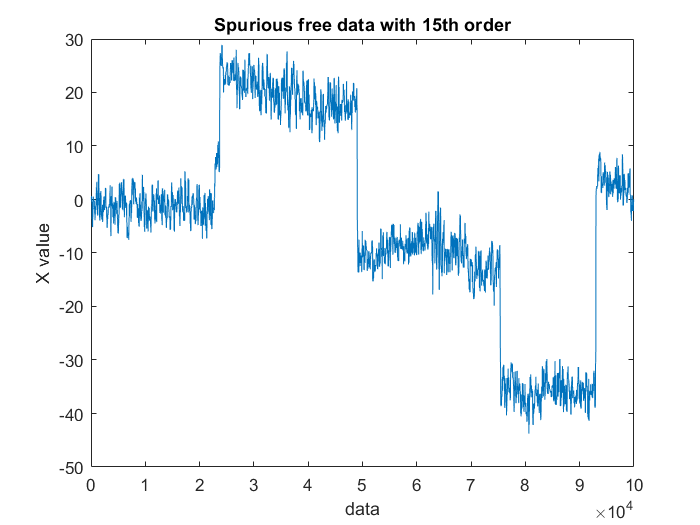

for i = 1: length(sanitized_data)   
    spurious_free_data2(i).x = medfilt1(sanitized_data(i).x, 15);
end

plot(spurious_free_data2(1).time, spurious_free_data2(1).x)
title('Spurious free data with 15th order');
xlabel('data');
ylabel('X value');

**Ans:**

Median filtering involves taking a window and shifting the window along the data signal, sample by sample. For the samples within a window, we calculate the median, differences in standard deviation in the window. Once, we detect a sample having larger standard deviation difference than the standard deviation of the window, we replace the sample with the median of the window and thus bring the sample to the center of the signal and cleans it up.

We have implemented 10th order and 15th order 1D median filtering. The 10th order median filter is better than the 15th order median filter. But we need to take care that we don't take large windows of the data as that would just move large number of points to the median of that window and that would not be very informative. 

**Q6 Use the waveletAnalyzer tool to explore how wavelet denosing can be applied to denoise the data records. **

processed_data_sample = spurious_free_data(1).x

processed_data_sample =          0         0         0    0.0732    0.4813    0.4813   -0.1603   -0.1603    0.0842   -0.4948    0.0842    0.2872    0.2872   -0.2639   -0.2639   -2.4053   -1.8527   -3.2708   -4.4046   -4.4046   -4.4046   -5.9006   -4.4046   -4.4046   -4.4046   -3.2708   -4.0308   -6.2912   -3.7617    0.4373   -2.4604    0.4373    1.0245    1.0245   -0.7153   -0.7153    0.8035    0.8035    0.3162   -1.2025   -0.0686   -1.3654   -1.3654   -0.0686   -0.0686   -0.0686   -1.0197   -1.0197   -1.0197   -0.8213


processed_data_time = spurious_free_data(1).time

processed_data_time = 	1.0e+05 *

         0    0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060


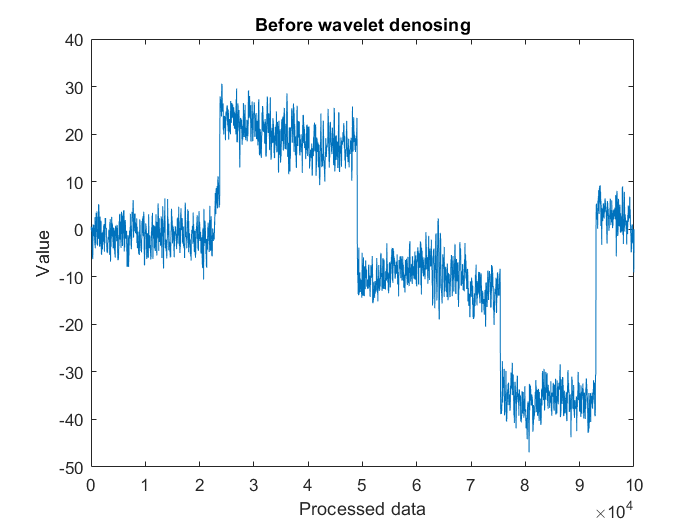

% Denoise Signal using the Discrete Wavelet Transform (DWT)

% Generated by MATLAB(R) 9.9 and Wavelet Toolbox 5.5.
% Generated on: 28-Jul-2021 11:34:31

processed_data1 = wdenoise(processed_data_sample,4, ...
    'Wavelet', 'db6', ...
    'DenoisingMethod', 'Bayes', ...
    'ThresholdRule', 'Median', ...
    'NoiseEstimate', 'LevelIndependent');

plot(processed_data_time, processed_data_sample)
hold on;
title('Before wavelet denosing');
xlabel('Processed data');
ylabel('Value');
hold off;

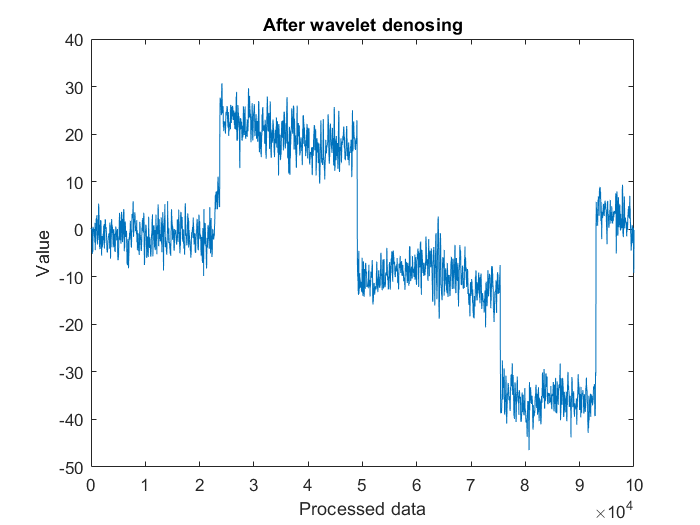

plot(processed_data_time, processed_data1)
hold on;
title('After wavelet denosing');
xlabel('Processed data');
ylabel('Value');
hold off;

After several expirements, we have found the daubechies wavelet with 6 number and level 4 to be the best denoised signal.The above illustrated plot captured the denoised signal after applying the same. 

**Q7 ** **Implement a full wavelet denosing approach for the full set of 100 data records.**

**Discuss whether or not (and why) wavelet denoising provides a improved denosing approach over classical noise fifitering methods for the given data records *****i.e.*****, If you applied a standard low pass filtering approach to the data what would the results be?**

denoised_data = [];
for i = 1:length(spurious_free_data)

    a = spurious_free_data(i).x;
    denoised_data(i).x = wdenoise(a,4, ...
    'Wavelet', 'db6', ...
    'DenoisingMethod', 'Bayes', ...
    'ThresholdRule', 'Median', ...
    'NoiseEstimate', 'LevelIndependent');   
    denoised_data(i).time = data(i).time;
end

save('processed_data_details.mat')

**Ans : **

Wavelet denoising approach would cover finite time domain and finite frequency range and thus provides a compact support in time and frequency. Wavelets can tradeoff the small time resolution with much broader frequency resolution. This is useful in case of non-stationary signal and detection of sudden change because it can capture high frequency signals. As observed in the plots above, the provided data is non-stationary and the means are changing over time and the wavelet denoising can help in this case as we can capture these sudden high frequency changes in the data.

Frequency domain tools such as Fourier analysis considers the same frequency and time domains and does not allow the trade off between the time scale and frequency scale as provided by the wavelet denoising approach. So for example, in case of sinusiods signals, they have fixed frequency but they persist infinitely over time and fourier is poor in detecting these kind of signals

The low pass filtering approach would only let the low frequency signals through and won't let the high frequency through. So low pass filter would smear the edges of the high frequency signal. Therefore, for the provided non-stationary dataset, a wide low pass filters would change the original signal and location of the edges of the high frequency signal. Thus, low pass filtering would not be an appropriate approach for denoising the provided signal that has sudden changes.

Hence, wavelet denoising approach provides an improved approach over classical noise filtering methods.